## Model of the system

continuous time mdel

s = tf('s'); 
sys = (1.0117*s^2 + 2.1709*s +1.4949)/((s + 1.09)^3)

sys =
 
    1.012 s^2 + 2.171 s + 1.495
  --------------------------------
  s^3 + 3.27 s^2 + 3.564 s + 1.295
 
Continuous-time transfer function.



t = 0:0.01:10;
figure(1), step(sys, t'), hold on       % step response of the approximated plant
sys2 = 1/(s+1-exp(-s)*exp(-2))

sys2 =
 
  A = 
            x1       x2       x3
   x1        1        0        0
   x2        0        1       -2
   x3      0.5      0.5  -0.1353
 
  B = 
       u1
   x1   0
   x2   0
   x3  -1
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1
   y1   0
 
  E = 
       x1  x2  x3
   x1   0   1   0
   x2   0   0   0
   x3   0   0   0
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 1 
 
Continuous-time state-space model.



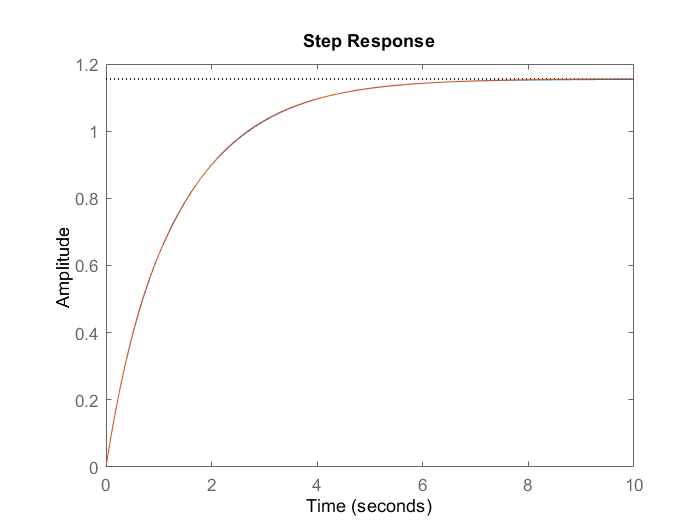

step(sys2, t')     % step response of the plant

% [num, den]= tfdata(sys)
num = [0 1.0117 2.1709 1.4949];
den = [1 3.2700 3.5643 1.2950];
[a, b, c, d] = tf2ss(num, den);

discretize

[am, bm, cm, dm]= c2dm(a, b, c, d, 0.2);

augmented system

A = [am zeros(size(am, 1), size(cm,1), 1); cm*am eye(size(cm, 1))], B = [bm; cm*bm], C = [zeros(size(cm, 1), size(am, 1)) 1], D = 0

A =     0.4726   -0.5316   -0.1856         0
    0.1433    0.9412   -0.0208         0
    0.0161    0.1959    0.9985         0
    0.8133    1.7983    1.2598    1.0000


B =     0.1433
    0.0161
    0.0011
    0.1816


C =      0     0     0     1


D = 0

## MPC

parameters

Np = 20; Nc = 4; R = eye(Nc); rs = 1; Rs = rs*ones(Np, 1);
[F, phi] = F_phi(A, B, C, Np, Nc);
E = phi'*phi + R;

constraints

M_deltaU = [-1 0 0 0; 0 -1 0 0; 1 0 0 0; 0 1 0 0];
M_u = [-1 0 0 0; -1 -1 0 0; 1 0 0 0; 1 1 0 0];
M = [M_deltaU; M_u];
b_deltaU = [0.1 0.1 0.1 0.1]';

observer gain

poles = [0.1 0.2 0.3 0.4];
Kob = place(A', C', poles)';

initials

x = [0 0 0 0]'; x_est = [0 0 0 0]'; buf = []; buf2 = []; u = 0;
buf = [0 C*x C*x_est 0]; buf2 = [[0 1]' [0 0]'];

control

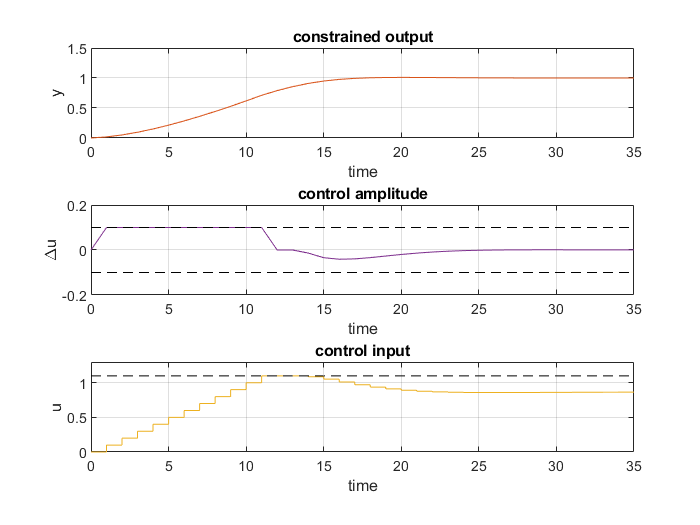

for k = 1:35
	FF = phi'*(F*x - Rs);
	b_u = [u; u; 1.1-u; 1.1-u]; b = [b_deltaU; b_u];
	deltaU = QPhild(E, FF, M, b); u = u+ deltaU(1);
	x_est = A*x_est + B*deltaU(1) + Kob*(C*x - C*x_est);
	x = A*x + B*deltaU(1);
	buf = [buf; k C*x C*x_est deltaU(1)];
	buf2 = [buf2; [k k+1]' [u u]'];
end

k = buf(:, 1); y = buf(:, 2); y_est= buf(:, 3); delta_u = buf(:, 4);
kk = buf2(1:end-1, 1); u = buf2(1:end-1, 2);
figure(2)
subplot 311, plot(k, [y, y_est]); axis([0 35 0 1.5]), grid on
title 'constrained output', xlabel 'time', ylabel 'y'
subplot 312, plot(k, delta_u), axis([0 35 -0.2 0.2]), grid on, hold on
plot(k, 0.1*ones(size(k)), 'k--'), plot(k, -0.1*ones(size(k)), 'k--')
title 'control amplitude', xlabel 'time', ylabel '\Deltau'
subplot 313, plot(kk, u), axis([0 35 0 1.3]), grid on, hold on
plot(kk, 1.1*ones(size(kk)), 'k--')
title 'control input', xlabel 'time', ylabel 'u'

stepinfo(y, k)

ans = struct with fields:
        RiseTime: 10.7464
    SettlingTime: 16.1741
     SettlingMin: 0.9095
     SettlingMax: 1.0097
       Overshoot: 0.9789
      Undershoot: 0
            Peak: 1.0097
        PeakTime: 20